Get PSD of $\mathbf{S}=\mathbf{g}\mathbf{g}^H$

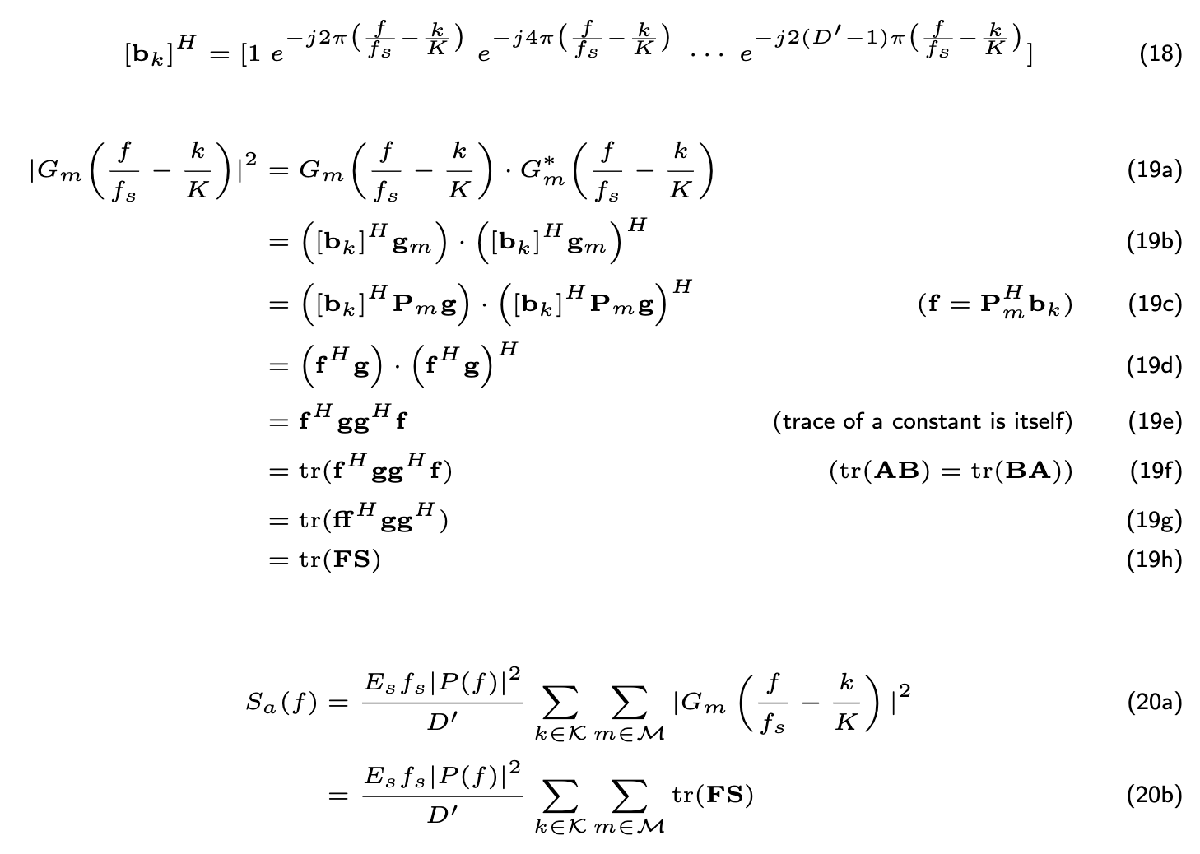

${\mathbf{P}}_m$ performs circular shift by $m$ and cyclic prefix.

function S_x = PSD_S(gfdm, S, fs, S_x_temp, fTs, P1)

K = gfdm.K; M= gfdm.M; L = gfdm.CP; Es = gfdm.Es; K_on = gfdm.K_on; M_on = gfdm.M_on;

Ts = 1/fs;

K_set = 0:K_on-1;
M_set = 0:M_on-1;

f_length = length(fTs);

% Check PSD_temp length
if f_length ~= length(S_x_temp)
    msg = 'PSD length is wrong.';
    error(msg);
end

D = K*M;
D_prime = D+L;

% F_cp
F_cp = [zeros(L, D-L) eye(L); eye(D)];

% P
P =  circshift(eye(D), 1, 1);

l = (0:D_prime-1)';

% F = ff^H = (Pm_H*b_f*b_k)(Pm_H*b_f*b_k)^H summation for all m and k

% Get Pm_H
m_card = size(M_set, 2);
Pm_H = zeros(D, D_prime, m_card);
for n = 1:m_card   
    % Get Pm matrix for each m
    Pm = F_cp * P^(-M_set(n)*K);
    Pm_H(:, :, n) = Pm';
end

% Get b_k_temp (b_k without the frequency element)
k_card = size(K_set, 2);
b_k_temp = zeros(D_prime, 1, k_card);
for n = 1:k_card
    % b_k_temp vector for each k
    b_k_temp(:, :, n) = exp(-1i * l * 2*pi*(-K_set(n)/K));
end

% Calculate the PSD for each normalized frequency fTs
for idx = 1:f_length
    % b_k vector
    b_k = exp(-1i * l * 2*pi*fTs(idx)) .* b_k_temp;

    F = zeros(D, D);
    for i = 1:m_card
        for j = 1:k_card
            f_vec = Pm_H(:, :, i) * b_k(:, :, j);
            F= F + f_vec * f_vec';
        end
    end

    S_x_temp(idx) = sum(reshape(transpose(F), [], 1) .* reshape(S, [], 1));
end

% S_x is a real affine expression
S_x =  ((Es/D_prime)*(P1.^2)) .* real(S_x_temp);
end